# InstrumentToolBox

## Instrument Connection & Configuration

%make sure ports were actually closed
HP54601B = []; %#ok<NASGU> 
FG100 = []; %#ok<NASGU> 

% Create the serial port object for the scope and connect to it.
%port1 = "COM24";
port1 = "COM15";
baudrate1 = 115200;
HP54601B = serialport(port1,baudrate1,"Timeout",60);
configureTerminator(HP54601B, "LF")
pause(1)

% Create the serial port object for the Function generator and connect to it.
%port2 = "COM23";
% port2 = "COM14";
% baudrate2 = 9600;
% FG100 = serialport(port2,baudrate2);
% configureTerminator(FG100,"LF")

% writeline(HP54601B, '*CLS')
% writeline(HP54601B, 'eras')

%Setup Funcion generator for remote control
%9 --  REN -- Remote (Enable remote control)
%25 -- LLO -- Local Lock Out (loc out frontend)
%20 -- DCL -- Device Clear (clear registers and initialise comm protocols)
%write(FG100,[9 25 20],"int8")
% Read the ID's of the devices
ScopeData = writeread(HP54601B, '*IDN?');
%FuncGenData = writeread(FG100, '*IDN?');
%print them
%disp(FuncGenData)
disp(ScopeData)

HEWLETT-PACKARD,54601B,0,1.2


## Instrument Control

%set data
%writeline(FG100, 'FREQ 5000');
%writeline(FG100, 'LEVEL 1.5');

%read data again
%writeline(HP54601B, 'aut')
%writeread(HP54601B, 'MEAS:FREQ?')
%writeread(HP54601B, 'MEAS:VAMP?')

%capture waveform from scope
writeline(HP54601B, 'DIGITIZE CHAN1')
pause(5)
%set up waveform data output type
writeline(HP54601B,'WAV:FORM ASC')
writeread(HP54601B, 'WAV:FORM?')

ans = 'ASC'


%aquire required data from scope
%%Waveform
wav_raw = writeread(HP54601B, 'WAV:DATA?')

wav_raw = '#80000800093,183,166,158,176,186,165,161,183,188,164,69,96,95,74,70,94,98,78,74,90,185,160,163,184,185,161,158,185,182,167,71,87,98,72,71,94,99,72,73,184,188,165,157,175,187,166,158,182,185,163,69,90,94,79,69,92,98,77,73,184,183,159,162,184,184,170,163,176,185,166,70,90,99,78,72,93,94,80,72,90,184,163,157,178,185,161,160,182,185,167,71,96,94,73,72,96,99,80,71,90,184,163,158,183,186,160,157,185,184,159,72,91,93,73,69,87,95,79,69,93,187,166,162,185,188,168,162,181,185,164,69,92,99,73,74,89,96,80,72,94,183,169,162,177,187,169,159,175,185,167,75,93,92,77,74,92,92,76,75,184,186,161,158,176,187,166,158,179,187,163,69,97,97,74,76,88,95,72,75,95,185,163,161,177,185,164,163,185,188,159,71,91,98,78,72,96,96,74,72,92,186,163,158,181,187,159,162,182,187,159,69,95,95,71,73,89,99,78,75,97,187,164,158,178,187,169,160,186,186,165,72,88,97,71,72,95,93,70,70,184,186,161,161,177,187,163,162,184,187,165,70,90,99,74,75,91,99,79,70,93,183,162,157,179,181,160,158,183,186,167,70,96,97,79,69,96,98,7

timeDuration_raw = writeread(HP54601B, 'TIM:RANG?')

timeDuration_raw = '+1.00000000E-001'

## FFT

% Fs = 20000000 (20Ms/s)
%Scaling = 1v/div
% time/Div = 50ms/div
% Actual signal freq = 50Hz
%horizDiv = 10 (not actually needed but good to know)
%scope horizontal resolution = 500
%scope vertical resolution == 255

%simulated values
%wav_raw = '#800008000128,124,120,116,115,111,107,104,103,98,96,93,91,90,90,87,86,85,84,84,84,84,84,85,87,88,90,91,92,94,97,99,103,107,107,112,114,119,123,125,128,132,135,140,143,145,149,154,154,158,160,164,167,169,170,173,173,175,177,176,176,177,176,174,174,171,170,167,166,164,160,156,155,151,149,143,140,140,135,132,127,124,119,118,114,109,107,106,103,99,97,94,92,91,88,88,86,85,85,83,83,83,84,85,86,88,90,91,93,95,97,100,103,106,109,111,114,117,120,124,129,133,136,140,143,145,151,153,156,160,160,164,167,169,171,173,173,175,176,176,177,176,175,174,172,171,170,168,165,164,161,158,155,151,148,146,142,138,135,132,128,124,121,116,113,111,107,104,102,99,97,93,91,89,89,88,85,85,85,84,84,84,84,85,86,87,89,91,94,95,97,99,103,105,109,113,116,117,123,125,129,133,135,139,142,146,149,154,155,158,160,164,166,169,170,172,174,175,176,176,176,177,176,174,173,172,170,168,167,162,160,156,153,152,147,146,142,139,133,130,129,122,122,116,112,112,108,105,100,99,97,94,93,90,88,87,85,86,84,84,83,83,84,85,86,88,88,89,93,95,97,100,102,108,109,112,114,118,121,124,129,134,136,139,143,146,149,151,156,158,161,164,166,169,171,172,173,175,176,176,177,177,175,174,173,171,171,169,166,163,158,157,156,150,149,144,142,138,135,133,126,124,121,119,113,110,107,105,102,99,96,93,92,90,89,88,86,85,85,84,83,84,84,85,86,88,90,90,92,95,97,100,102,105,109,112,116,119,121,127,129,130,136,140,142,147,151,152,157,159,162,164,166,169,172,173,174,176,177,177,177,176,175,174,172,172,169,168,165,163,161,158,156,150,148,145,141,139,134,132,127,126,121,117,115,111,108,104,102,99,97,94,92,89,89,87,85,85,84,84,83,83,84,85,87,88,88,90,93,95,96,100,102,106,110,111,114,119,122,125,127,131,137,139,143,146,149,153,155,159,162,165,166,167,171,173,174,174,175,177,176,176,176,174,173,171,169,169,165,163,161,158,155,151,148,145,143,137,135,133,129,123,120,118,115,111,107,104,102,100,96,94,92,91,88,88,86,85,85,84,84,83,84,86,86,88,89,91,92,95,98,101,104,106,108,113,116,118,122,126,130,133,136,140,143,146,150,153,156,159,163,164,165,169,171,173,173,175,176,177,177,177,175,174,173,171,170,168,165,162,160,158,155,151,148,143,142,138,133,133,129,123,121,118,114,111,108,106,101,98,98,94,92,89,88,87,86,84,84,83,83,83,84,85,86,88,89,91,93,95,97,101,103,106,109,111,116,119,122,125,128,133,135,138,144,147,151,153,155,160,161,164,167,168,170,174,173,174,176,175,177,176,175,174,174,172,170,168,167,163,160,158,154,151,150,145,141,136,136,130,127,124,120,117,115,111,109,104,102,99,96,94,91,89,89,87,86,86,84,83,83,84,84,85,87,87,89,90,92,95,97,100,103,106,110,112,114,119,121,125,130,132,136,140,144,145,149,152,155,157,162,163,166,168,170,172,174,174,176,176,177,176,175,175,173,171,169,167,166,164,161,157,154,152,148,146,142,138,135,130,128,122,120,116,115,112,108,104,103,99,96,94,92,91,89,87,86,85,85,83,84,83,85,85,86,87,89,91,92,95,97,100,102,106,111,112,115,117,122,126,129,134,135,139,142,146,148,151,156,159,161,165,166,169,171,172,174,175,175,176,177,176,175,174,173,172,170,167,165,163,160,158,156,152,150,146,141,139,135,130,127,124,120,117,114,109,108,106,102,98,96,94,93,90,90,88,86,85,84,84,83,84,84,85,87,87,89,90,92,94,98,99,102,105,107,112,115,117,120,125,128,132,136,140,141,147,150,153,156,158,162,164,166,169,171,172,173,175,175,176,176,176,175,174,172,172,170,167,166,163,159,158,156,153,149,145,142,139,134,131,127,123,121,116,113,112,109,104,102,100,96,95,93,90,89,87,85,85,84,84,83,84,84,87,86,88,89,91,92,96,98,99,101,106,108,112,115,118,122,125,130,131,135,139,141,148,148,152,157,159,160,163,166,168,170,172,173,173,175,176,177,176,176,174,173,172,169,168,165,162,160,157,154,153,148,145,142,139,134,131,128,124,121,117,113,111,107,105,102,100,98,94,92,90,88,87,86,85,83,83,83,83,84,85,85,87,88,91,93,94,96,99,103,105,109,113,115,119,121,126,127,133,134,138,144,146,149,151,157,158,161,164,166,169,171,171,173,175,175,177,177,176,175,174,173,171,170,168,165,163,160,158,155,153,149,146,144,139,134,132,128,124,121,119,114,111,107,106,102,99,96,94,92,90,89,87,86,85,84,84,83,83,85,85,85,87,89,90,92,94,96,100,103,106,109,111,116,119,122,127,129,133,136,138,143,145,149,152,154,159,163,163,167,169,171,172,173,175,175,176,177,177,176,175,173,172,170,169,166,165,161,158,155,151,148,146,141,139,135,131,128,124,122,117,115,110,108,106,102,98,98,94,93,91,89,87,86,85,84,84,84,84,84,84,86,87,89,90,92,94,97,101,104,106,109,111,115,117,121,126,128,133,135,139,144,146,150,153,157,158,160,164,165,168,170,171,173,175,176,177,177,176,176,174,173,171,169,167,165,163,161,158,155,151,148,146,141,139,135,131,128,123,121,119,114,111,109,105,103,99,97,94,92,90,89,87,86,85,85,84,83,84,85,85,86,87,89,91,93,95,97,100,102,104,109,111,114,117,120,126,129,131,136,140,143,146,150,153,155,159,160,164,166,169,170,172,175,175,175,177,177,177,176,175,173,171,170,167,165,162,162,159,156,151,147,144,143,139,134,132,129,126,122,117,114,110,108,105,101,99,97,96,91,90,87,87,86,84,85,84,83,83,84,85,87,87,88,90,92,95,96,101,101,106,108,112,114,118,122,125,127,132,136,140,142,145,149,153,154,158,161,164,167,169,170,172,172,174,175,176,177,176,175,175,172,172,170,168,165,163,161,159,155,153,150,145,141,140,135,132,127,125,123,118,115,111,109,104,102,101,97,94,93,90,89,88,86,85,84,83,83,84,84,85,87,88,89,90,92,94,97,100,101,105,109,113,113,119,123,126,129,131,136,140,143,146,150,153,155,158,161,164,167,168,170,172,174,175,176,176,177,176,176,174,173,171,169,168,166,164,160,157,155,154,149,145,142,139,136,131,129,125,122,118,114,109,109,106,102,99,96,95,91,89,88,89,86,85,84,84,83,84,85,86,87,87,89,90,92,94,96,100,101,106,107,111,115,118,121,126,129,133,135,141,143,146,149,151,154,159,160,163,167,168,170,172,174,175,176,177,178,177,176,176,173,171,169,167,167,164,160,158,154,152,148,146,142,139,135,133,127,124,122,118,113,111,106,105,101,100,97,95,92,90,88,88,85,85,85,83,83,84,84,85,86,87,89,91,93,94,96,101,101,105,109,112,115,119,122,124,128,134,134,138,143,145,149,153,156,159,161,164,166,169,170,171,173,175,175,176,177,176,176,175,173,172,169,168,165,162,161,158,156,152,149,146,143,140,136,133,130,125,122,117,115,113,108,106,102,99,98,95,93,90,89,87,87,86,84,84,83,84,85,85,86,88,88,91,92,95,97,100,103,106,107,111,115,118,121,124,129,131,134,140,141,145,149,151,155,157,160,163,165,169,171,171,173,174,175,177,176,176,175,175,173,171,170,167,165,164,161,157,155,151,149,145,140,138,136,132,127,123,121,119,116,112,106,105,102,99,97,95,93,89,90,87,86,86,84,84,83,84,84,86,86,88,89,91,93,94,96,99,102,106,106,110,114,117,122,124,129,132,134,141,141,147,150,153,156,158,161,163,167,169,169,172,174,175,176,177,177,176,176,174,173,171,170,168,166,164,161,157,154,152,149,146,142,139,136,133,130,124,123,118,113,112,108,104,102,100,98,96,92,91,89,87,87,85,84,84,83,84,84,85,86,87,88,91,92,95,96,100,101,107,108,113,116,119,120,124,129,131,137,139,142,144,149,152,154,159,160,164,166,168,170,171,174,174,175,177,177,176,176,175,173,173,170,167,166,165,161,160,155,152,151,145,143,140,135,133,129,125,120,117,115,111,109,106,103,99,98,95,93,91,89,87,87,85,85,84,83,84,84,85,85,88,89,91,92,94,97,99,101,104,108,111,116,118,123,124,129,131,134,140,144,146,148,151,155,158,161,164,166,169,170,172,173,174,176,176,176,176,175,174,173,173,169,168,165,164,162,158,156,151,151,144,142,140,135,132,129,124,122,117,114,111,108,106,103,101,96,96,93,91,89,87,86,85,84,83,83,84,84,85,87,87,89,90,92,96,96,99,102,105,109,113,115,119,120,123,129,131,136,138,142,145,148,152,156,159,161,163,166,169,170,173,173,174,175,176,177,177,176,175,173,172,171,168,165,164,159,159,156,151,150,148,142,138,136,130'
%timeDuration_raw = '5.000000E-001'

%wav_raw = '#800008000110,108,91,105,115,104,90,108,116,91,98,115,106,95,108,116,103,93,115,114,93,95,113,97,92,108,108,100,92,116,108,90,111,115,99,91,111,109,93,100,115,98,90,104,112,99,92,113,98,87,104,110,94,93,112,109,89,106,113,98,89,112,106,93,98,113,99,88,105,113,94,91,111,102,89,97,113,93,92,110,110,93,97,117,113,92,103,111,106,93,114,109,93,103,122,97,94,113,115,101,94,117,112,95,108,119,100,105,117,118,98,109,124,114,110,115,125,101,109,133,118,107,120,128,113,103,128,119,104,111,129,110,103,121,130,107,116,129,119,105,118,131,113,107,127,124,108,116,131,112,109,127,127,110,114,131,125,107,124,130,113,109,131,127,108,123,138,112,114,132,135,119,114,139,127,114,128,139,123,118,140,137,120,134,144,134,127,138,145,124,133,149,142,125,136,148,129,126,149,149,120,134,150,136,124,145,143,131,129,148,144,126,138,149,136,126,151,139,129,134,151,131,126,143,149,128,134,150,143,125,142,150,132,130,146,139,122,132,150,139,125,143,153,125,137,153,133,125,150,151,131,134,151,147,127,143,150,136,124,140,150,126,133,148,140,125,152,151,130,129,148,140,127,137,151,142,127,146,148,133,133,151,135,126,137,148,137,126,146,145,122,137,149,138,126,143,147,126,132,147,131,121,141,146,123,126,148,140,124,133,144,137,114,129,137,115,123,139,134,115,128,135,119,111,131,132,111,124,134,120,108,125,135,117,115,135,121,108,126,132,113,108,127,127,108,119,133,124,108,123,134,108,111,130,125,107,118,132,110,113,127,128,105,119,134,122,107,123,122,110,109,125,113,101,115,125,105,102,123,118,105,106,123,103,97,118,114,103,101,110,110,91,107,114,95,95,118,106,90,111,113,99,93,108,116,95,93,115,107,90,103,114,99,91,112,109,92,94,115,102,88,103,114,95,96,113,110,90,102,116,97,94,114,114,94,100,114,99,92,109,118,98,100,116,103,88,101,122,97,94,114,119,95,100,117,97,90,111,111,92,99,114,108,88,112,112,96,94,120,104,96,103,110,101,87,118,113,93,92,111,104,89,104,112,99,94,112,105,89,99,113,95,90,104,113,91,91,115,102,90,103,115,102,98,115,118,95,109,120,109,98,115,120,101,110,123,116,102,117,127,108,108,127,122,104,113,131,111,106,122,129,116,115,133,125,104,126,134,113,116,131,128,109,124,137,120,103,123,128,112,107,127,126,108,121,130,111,110,128,124,107,114,133,118,109,123,133,113,114,134,129,111,123,140,122,120,137,138,116,127,144,126,120,141,146,121,124,147,140,122,141,151,132,127,146,154,126,137,157,134,129,138,153,128,135,152,139,133,133,148,135,136,151,148,124,144,150,139,129,141,150,135,131,149,138,124,140,149,135,130,149,144,127,136,147,140,122,136,148,127,128,150,139,122,138,149,131,128,149,147,128,139,152,136,126,139,152,132,127,148,136,127,143,149,133,127,148,147,128,135,152,136,131,154,153,127,133,153,148,127,146,152,137,126,144,146,134,130,148,136,123,138,149,132,134,148,144,124,138,147,136,120,137,138,118,124,143,125,117,131,143,121,121,139,127,113,121,138,123,113,137,129,111,120,134,117,110,130,137,114,113,134,127,110,119,143,112,111,130,131,112,122,136,132,107,126,130,113,114,141,132,108,116,134,119,107,132,130,110,113,135,121,109,128,130,110,110,128,123,102,115,126,112,102,121,121,99,102,122,112,97,113,120,103,97,117,111,94,108,117,100,91,108,111,91,95,113,97,89,103,112,89,94,116,104,91,100,120,97,93,113,109,102,98,116,102,90,108,117,100,90,110,113,89,105,115,106,93,119,114,92,104,114,107,91,108,114,95,99,112,106,88,104,115,96,89,107,108,88,94,112,103,85,109,108,95,94,113,100,87,96,114,98,89,108,109,88,92,113,99,88,107,113,91,90,109,98,93,98,113,99,93,111,105,89,101,114,98,90,102,113,90,98,113,113,92,99,115,104,99,107,121,96,99,120,112,104,117,120,105,103,120,115,99,112,127,109,103,125,125,102,110,128,119,104,121,129,112,105,125,125,104,126,131,116,107,125,129,110,113,130,114,105,120,127,106,110,130,126,107,119,130,109,108,127,123,106,116,132,126,114,127,138,117,110,133,130,118,126,135,123,120,130,136,122,127,141,130,114,130,142,123,120,140,137,128,132,147,127,122,152,147,124,131,149,133,125,143,145,133,128,148,143,123,138,151,133,126,144,143,128,131,149,142,123,141,149,134,131,146,142,126,142,152,138,126,149,146,127,137,150,137,132,141,144,125,124,153,145,124,138,147,134,133,149,143,127,140,150,140,131,141,150,131,127,145,144,133,136,152,135,126,146,149,131,134,151,135,126,143,151,136,130,148,143,125,141,152,140,126,145,151,125,129,148,145,125,138,146,130,126,148,146,124,146,148,133,124,147,140,123,129,151,128,121,139,143,128,117,143,129,126,130,147,133,113,136,131,115,114,133,121,120,127,136,118,111,130,127,117,120,140,117,110,129,127,109,112,130,120,108,126,132,112,116,132,130,108,120,130,124,109,130,129,114,120,135,118,108,122,128,109,108,127,120,106,119,130,108,105,120,123,103,109,126,112,99,116,120,104,107,118,116,96,101,119,100,90,119,118,92,93,112,106,88,103,115,100,100,107,108,91,102,114,101,91,109,111,95,95,115,106,89,106,112,99,96,111,110,89,98,113,103,89,107,110,94,93,112,107,90,105,114,98,95,113,112,92,104,116,100,91,111,113,91,95,114,98,88,108,116,93,94,112,108,89,103,115,97,88,111,112,90,103,111,107,96,102,113,94,89,122,103,93,98,121,96,88,105,110,92,96,111,100,89,99,113,93,92,114,106,90,98,114,99,91,113,111,93,98,117,107,93,109,120,107,97,120,118,99,111,124,111,101,116,120,103,112,128,115,104,122,127,114,107,128,125,104,118,130,109,110,129,128,109,107,133,124,111,125,132,109,108,139,126,112,121,131,115,105,126,126,110,119,130,123,105,118,127,114,111,129,121,107,116,134,120,111,126,130,114,121,136,133,113,126,137,117,119,141,141,118,128,143,129,123,145,145,122,128,150,135,125,145,151,142,132,155,139,125,140,151,136,132,151,148,133,127,151,147,124,146,150,132,125,146,148,126,141,150,140,124,143,144,130,135,153,142,127,139,147,127,126,147,146,121,133,148,133,124,140,144,122,128,147,142,123,140,152,127,129,147,143,125,141,154,138,126,143,148,124,136,151,141,127,144,155,133,135,150,149,135,142,150,136,129,141,150,136,127,151,135,125,140,155,135,126,147,146,126,131,149,135,132,141,148,125,130,147,136,121,136,145,123,118,146,137,117,128,142,132,115,135,134,114,117,138,127,111,128,135,118,111,134,133,110,123,135,120,111,133,141,117,119,142,120,107,126,142,117,112,136,133,113,113,141,128,112,129,140,118,121,130,129,106,119,133,113,108,129,130,109,112,132,115,106,125,123,106,108,122,114,100,119,122,105,99,116,113,98,107,120,108,94,111,115,98,96,116,107,91,104,114,94,92,109,109,89,100,112,106,91,106,111,91,97,114,104,89,110,115,95,93,113,110,92,104,112,99,89,112,115,98,94,120,105,90,97,121,101,102,122,111,91,107,115,104,91,121,110,97,95,114,105,88,100,114,98,87,106,104,90,102,112,94,88,108,113,88,92,111,106,89,100,115,100,100,109,111,92,99,114,98,88,111,106,101,98,111,97,97,103,112,92,95,112,112,92,100,123,109,94,104,113,97,98,119,108,97,114,117,103,103,114,116,98,103,118,112,97,114,123,105,102,125,116,104,120,127,113,103,127,129,103,112,130,111,103,122,125,107,107,130,117,104,119,131,113,106,126,126,106,116,130,121,105,123,132,119,109,131,133,106,122,138,119,108,130,123,110,110,134,119,109,121,138,117,111,142,132,112,123,137,120,114,147,134,118,134,144,135,118,138,145,129,124,154,135,124,138,148,133,128,158,142,125,141,151,142,124,149,148,129,127,149,140,125,136,151,128,131,146,144,121,133,151,146,126,145,149,139,131,151,144,134,140,151,135,128,147,145,123,139,149,133,122,147,148,125,132,148,144,123,141,150,139,131,155,150,129,133,152,141,124,150,151,134,127,151,140,126,135,150,131,127,147,149,130,134,150,142,126,145,147,126,130,149,136,126,136,150,129,126,148,147,124,134,151,141,126,146,143,133,133,150,146,133,137,149,143,122,145,137,124,128,153,139,121,129,142,124,126,148,124,113,121,141,116,122,129,129,113,114,135,122,110,126,129,116,115,140,131,109,117,132,115,108,129,132,114,119,133,121,107,121,128,112,112,132,123,107,119,132,121,112,128,129,107,120,133,120,106,127,129,111,115,130,131,103,120,127,106,104,125,125,102,111,121,114,99,120,117,102,108,120,112,94,114,114,95,89,106,115,90,94,111,103,95,98,111'
%timeDuration_raw = '+1.00000000E-001'


%trim and convert waveform signal to 1 dimmension number array
wav_trimed = wav_raw(11:end)

wav_trimed = '93,183,166,158,176,186,165,161,183,188,164,69,96,95,74,70,94,98,78,74,90,185,160,163,184,185,161,158,185,182,167,71,87,98,72,71,94,99,72,73,184,188,165,157,175,187,166,158,182,185,163,69,90,94,79,69,92,98,77,73,184,183,159,162,184,184,170,163,176,185,166,70,90,99,78,72,93,94,80,72,90,184,163,157,178,185,161,160,182,185,167,71,96,94,73,72,96,99,80,71,90,184,163,158,183,186,160,157,185,184,159,72,91,93,73,69,87,95,79,69,93,187,166,162,185,188,168,162,181,185,164,69,92,99,73,74,89,96,80,72,94,183,169,162,177,187,169,159,175,185,167,75,93,92,77,74,92,92,76,75,184,186,161,158,176,187,166,158,179,187,163,69,97,97,74,76,88,95,72,75,95,185,163,161,177,185,164,163,185,188,159,71,91,98,78,72,96,96,74,72,92,186,163,158,181,187,159,162,182,187,159,69,95,95,71,73,89,99,78,75,97,187,164,158,178,187,169,160,186,186,165,72,88,97,71,72,95,93,70,70,184,186,161,161,177,187,163,162,184,187,165,70,90,99,74,75,91,99,79,70,93,183,162,157,179,181,160,158,183,186,167,70,96,97,79,69,96,98,79,72,89

wav_dec = str2num(wav_trimed) %#ok<ST2NM>

wav_dec =     93   183   166   158   176   186   165   161   183   188   164    69    96    95    74    70    94    98    78    74    90   185   160   163   184   185   161   158   185   182   167    71    87    98    72    71    94    99    72    73   184   188   165   157   175   187   166   158   182   185



%convert the NR3 format output string from the scope into a scalar
timeDuration = str2double(timeDuration_raw)

timeDuration = 0.1000


%because the signal is measured in the AC domain there needs to be a DC
%offset to make the signal show up correctly
dc_offset = 255/2; %data range divided by 2 
scaling_factor = (8) / 255;
 

%apply the scaling factor and offset to the signal
wav_scaled = (wav_dec - dc_offset) * scaling_factor

wav_scaled =    -1.0824    1.7412    1.2078    0.9569    1.5216    1.8353    1.1765    1.0510    1.7412    1.8980    1.1451   -1.8353   -0.9882   -1.0196   -1.6784   -1.8039   -1.0510   -0.9255   -1.5529   -1.6784   -1.1765    1.8039    1.0196    1.1137    1.7725    1.8039    1.0510    0.9569    1.8039    1.7098    1.2392   -1.7725   -1.2706   -0.9255   -1.7412   -1.7725   -1.0510   -0.8941   -1.7412   -1.7098    1.7725    1.8980    1.1765    0.9255    1.4902    1.8667    1.2078    0.9569    1.7098    1.8039


%wav_scaled = 2*sin(2*pi*50*time) + 0.5*sin(2*pi*150*time)


%To get the samepling Frequency you divide the time duration of the
%waveform capture with the amount of samples the signal has
Fs = length(wav_scaled)/timeDuration

Fs = 20000

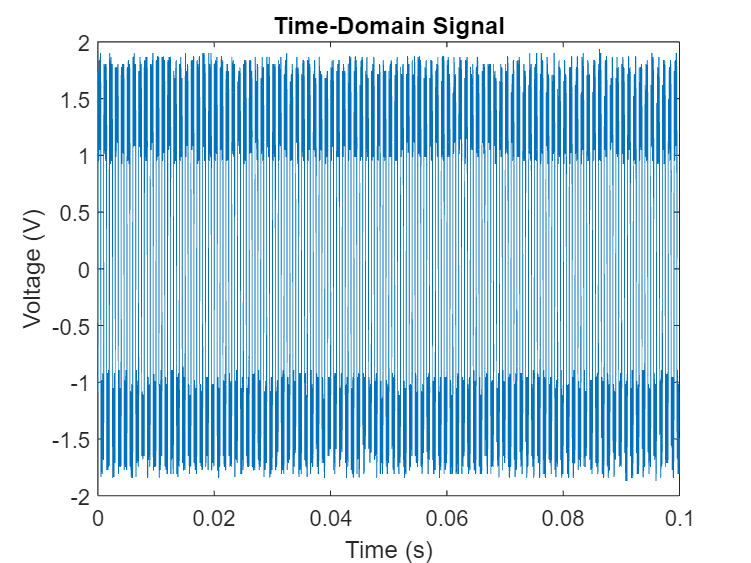



% Calculate the time vector based on the measurement duration
time = linspace(0, timeDuration, length(wav_scaled));




% Perform FFT
N = length(wav_scaled);
Y = fft(wav_scaled);
f = Fs * (0:(N/2)) / N;

% Compute the magnitude (amplitude) of the FFT result
magnitude = 2 * abs(Y(1:N/2 + 1));

% Plot the FFT results
%subplot(2, 1, 1);
plot(time, wav_scaled);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Time-Domain Signal');

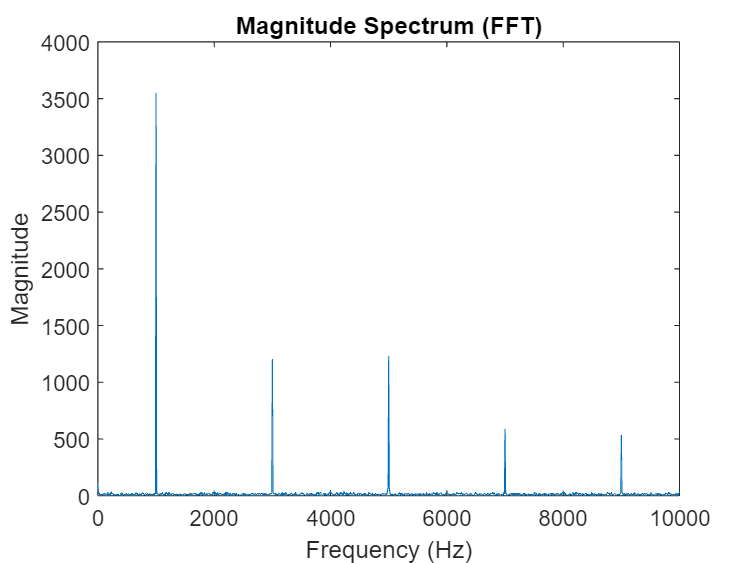


%subplot(2, 1, 2);
plot(f,magnitude);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum (FFT)');




%delete Serial port objects from existence after completing
clear HP54601B
clear FG100